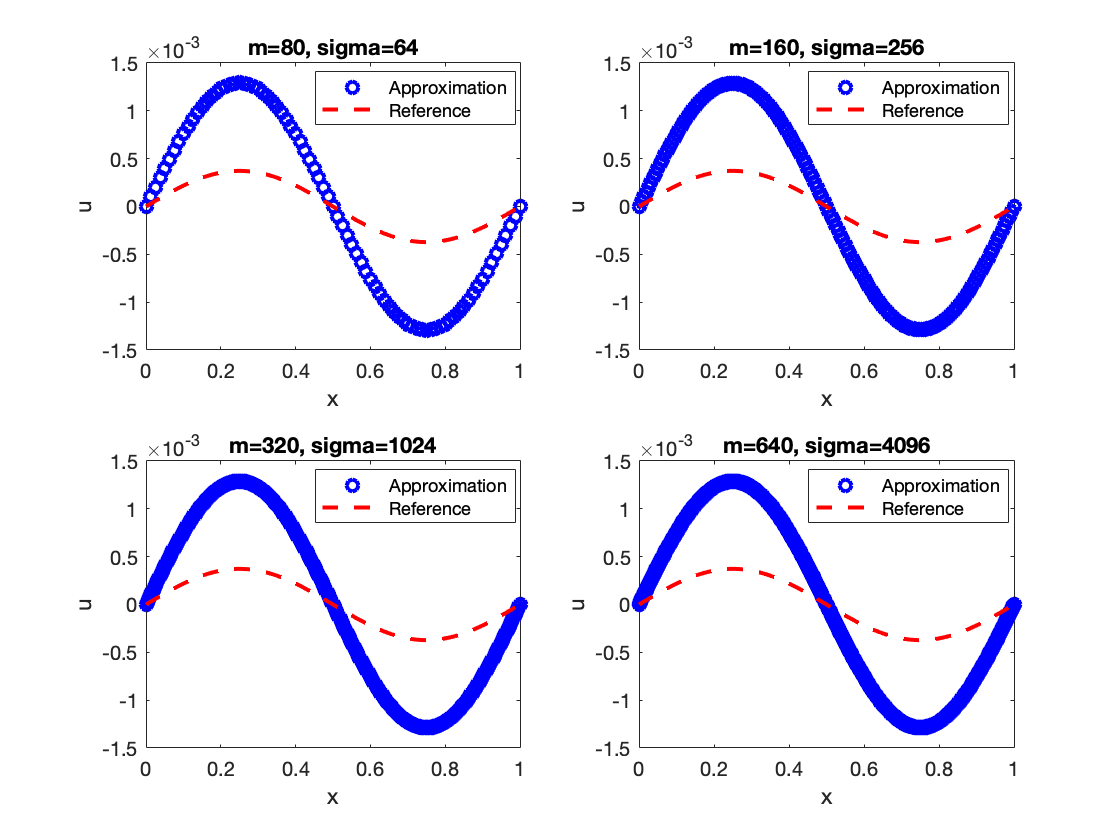

% Checking stability of BTCS for arbitrary dt and dx

%spatial domain [0, 1]
a=0;
b=1;
%initial condition (periodic function)
u0=@(x) sin(2*pi*x);

T = 0.2;
dt = 0.01;

err_l2dx=zeros(4,1);
dx = zeros(4,1);

for j = 1:4
    m=2^(j+2)*10;
    %Generate the grid
    x=linspace(a,b,m+1)';
    %grid/mesh size
    dx(j)=(b-a)/m;
    sigma = dt/(dx(j)^2);
    n_t=floor(T/dt);
    u=u0(x);
    A = diag(ones(1,m)*(1+2*sigma))+diag(ones(1,m-1)*(-sigma),1)...
        +diag(ones(1,m-1)*(-sigma),-1);
    A(1,m)=-sigma;
    A(m,1)=-sigma;
    for i=1:n_t
        u(1:m)= A\u(1:m);
        u(end) = u(1);
    end
    % After the n_t steps, if we still have T-n_t*dt to arrive at 
    % the final time T.
    if T-n_t*dt > 0
        dt = T-n_t*dt;
        sigma = dt/(dx(j)^2);
        A = diag(ones(1,m)*(1+2*sigma))+diag(ones(1,m-1)*(-sigma),1)...
        +diag(ones(1,m-1)*(-sigma),-1);
        A(1,m)=-sigma;
        A(m,1)=-sigma;
        
        u(1:m)= A\u(1:m);
        u(end)=u(1);
    end
    
    u_exact=exp(-4*pi^2*T)*sin(2*pi*x);
    
    subplot(2,2,j)
    plot(x, u, 'bo', 'LineWidth', 2);
    hold on
    plot(x, u_exact, 'r--', 'LineWidth', 2);
    hold off
    xlabel('x');
    ylabel('u');
    legend('Approximation', 'Reference', 'Location', 'best');
    title(['m=', num2str(m), ', sigma=', num2str(dt/dx(j)^2)])
    
    err_l2dx(j)=norm(u-u_exact, 2)*sqrt(dx(j));
end

format short e
disp("Numerical error in l_{2,dx} norm with different dx ")

Numerical error in l_{2,dx} norm with different dx 


order=@(e) log(e(1:end-1)./e(2:end))./log(2);

disp([dx err_l2dx [0; order(err_l2dx)]])

   1.2500e-02   6.5000e-04            0
   6.2500e-03   6.4801e-04   4.4252e-03
   3.1250e-03   6.4751e-04   1.1070e-03
   1.5625e-03   6.4739e-04   2.7681e-04



The code is always stable because the curves have the same shape no matter how sigma is changed. BTCS is unconditionally stable. The approximation does not improve as dx getting smaller, because sigma is changing (increasing) as we fixed dt and change dx, instead of considering omega as a constant. 